%{
    Date: 2023/08/23
    Filename: SignalCorrelation.mlx
    Author: Paul Barron
    Description: This script calculates correlations of the raw original
    signals and then plots all the combinations of signals within that
    file.
%}

% Calculat the R2 values for each combination of signals in each file
warning('off','all')

rawDataArray = {numOfFiles};
for fileIndex = 1 : numOfFiles
    % Load the data for the current file
    rawDataStruct = load(dataSubfolder + filenames(fileIndex) + ".mat");
    rawDataArray{fileIndex} = struct2array(rawDataStruct); 
end

r2Val = zeros(numOfSignals, numOfSignals);
r2Values = zeros(numOfFiles, numOfSignals, numOfSignals);
for fileIndex = 1 : numOfFiles
    for sensorIndex1 = 1 : numOfSignals
        for sensorIndex2 = 1 : numOfSignals
            sig1 = rawDataArray{fileIndex}{sensorIndex1,2};
            sig2 = rawDataArray{fileIndex}{sensorIndex2,2};
            mdl = fitlm(sig1, sig2);
            R2 = mdl.Rsquared.Ordinary;
            r2Val(sensorIndex1, sensorIndex2) = R2;
            r2Values(fileIndex, sensorIndex1, sensorIndex2) = R2;
        end
    end
end

% Print one of the matrices to Latex file
addpath('C:\Users\PaulBarron\Dropbox\Thesis\matrix2latex')
fileNum = 4;
M = r2Values(fileNum, :, 1)';
for i = 2:size(r2Values,3)
    M = [ M r2Values(fileNum,:, i)' ];
end

rowLabels = { '07', '10', '12', '17', '20', '28', '31', '32', '33', '34', '35', '36' };
columnLabels = rowLabels;

matrix2latex(M, "..\Latex Document\tables\correlationTable" + fileNum + ".tex", 'rowLabels', rowLabels, 'columnLabels', columnLabels, 'alignment', 'c', 'format', '%-6.2f', 'size', 'tiny');

## Plot table for the correlation of each raw signal in a particular file

arr = [1:1:12];
labels = arrayfun(@num2str, arr, 'UniformOutput', 0);
for fileIndex = 1:numOfFiles
    fprintf("Filenumber #%i", fileIndex)
    arrTable = array2table(squeeze(r2Values(fileIndex, :, :)), 'VariableNames',	labels)
end

Filenumber #1

arrTable = 12×12 table
        1             2             3             4            5             6             7             8             9             10         11         12     
    __________    __________    __________    _________    _________    ___________    __________    _________    ___________    __________    ____    ___________
             1       0.92861      0.072707       0.3675     0.065114       0.051261       0.21795      0.20367        0.20573       0.21796    -Inf        0.16393
       0.92861             1      0.070488      0.44055     0.063314       0.072

Filenumber #2

arrTable = 12×12 table
         1              2              3             4              5              6             7              8             9             10          11         12     
    ___________    ___________    ___________    __________    ___________    ___________    __________    ___________    __________    ___________    ____    ___________
              1        0.29732        0.14225      0.058199        0.13897        0.10511    6.3074e-06        0.10091      0.057402     0.00054671    -Inf      0.0095892
        0.29732              1        0.07749      0.001

Filenumber #3

arrTable = 12×12 table
         1             2              3             4              5              6              7              8             9             10         11         12    
    ___________    __________    ___________    __________    ___________    ___________    ___________    ___________    __________    __________    ____    __________
              1       0.11609       0.077339     0.0021121        0.06993       0.013875          0.163        0.13748     0.0018398     0.0096207    -Inf      0.045023
        0.11609             1     0.00045767     0.0043065    

Filenumber #4

arrTable = 12×12 table
         1              2              3             4              5             6              7              8             9             10         11         12     
    ___________    ___________    ___________    __________    ___________    __________    ___________    ___________    __________    __________    ____    ___________
              1       0.066675     2.1472e-05      0.010025     0.00013623       0.01963       0.038803         0.4545       0.45591      0.026689    -Inf      0.0038445
       0.066675              1       0.022975    9.3809e-05

Filenumber #5

arrTable = 12×12 table
        1              2             3             4              5             6              7              8             9             10         11         12     
    __________    ___________    __________    __________    ___________    __________    ___________    ___________    __________    __________    ____    ___________
             1        0.75956    0.00093403       0.27822      0.0020498     0.0017373         0.1786        0.26871     0.0003167       0.47184    -Inf       0.044473
       0.75956              1     0.0093203       0.25463      0.

Filenumber #6

arrTable = 12×12 table
       1           2           3          4          5           6             7              8              9             10         11         12    
    ________    ________    _______    _______    _______    __________    __________    ___________    ___________    __________    ____    __________
     0.46022    -0.31574     -2.492    -1.8156     -2.492    7.9936e-15    6.5503e-15    -1.3767e-14    -2.6645e-15    7.5495e-15    -Inf    1.3323e-15
     0.57351    -0.99308    -2.3426    -1.6475    -2.3426    1.0325e-14      1.41e-14    -4.4409e-16    -2.8866e-

Filenumber #7

arrTable = 12×12 table
        1             2             3             4             5             6             7             8             9             10           11            12    
    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    _________    __________
             1      0.054205     0.0028762       0.96569     0.0031986    0.00064486        0.7006       0.62882      0.037237     0.0013322        0.615      0.040532
      0.054205             1      0.012766      0.025016      0.0

Filenumber #8

arrTable = 12×12 table
        1              2             3             4             5             6              7             8              9             10          11         12     
    __________    ___________    __________    __________    __________    __________    ___________    __________    ___________    ___________    ____    ___________
             1        0.56081        0.2965       0.96089       0.26266       0.10073        0.86871        0.8844      2.712e-07       0.023539    -Inf        0.10469
       0.56081              1       0.35655       0.70595       0

Filenumber #9

arrTable = 12×12 table
       1            2             3           4            5            6             7             8            9            10            11            12    
    ________    __________    _________    ________    _________    __________    __________    _________    __________    _________    __________    __________
           1       0.39589      0.24849     0.99824      0.21203      0.068315       0.24161     0.066263      0.010467     0.054453       0.39886      0.015498
     0.39589             1    0.0047139     0.39198    0.0032011    1.2352e-06       0

Filenumber #10

arrTable = 12×12 table
        1           2           3           4           5           6           7           8           9          10          11          12   
    _________    ________    _______    _________    _______    _________    ________    ________    _______    ________    ________    ________
            1     0.91819    0.44892      0.98375    0.36311    0.0090659     0.89232     0.81397    0.68083     0.88802     0.76025     0.34929
      0.91819           1    0.60913      0.85927    0.52577     0.053112     0.96292     0.85726    0.71787     0.96057     0.81816  

Filenumber #11

arrTable = 12×12 table
        1             2              3             4              5              6             7              8             9             10          11         12     
    __________    __________    ___________    __________    ___________    ___________    __________    ___________    __________    ___________    ____    ___________
             1       0.77717        0.34945       0.99532        0.30513       0.094727      0.035598      0.0011237      0.012568        0.04119    -Inf       0.087751
       0.77717             1         0.1995       0.78872     

Filenumber #12

arrTable = 12×12 table
        1              2             3              4             5             6              7             8             9             10         11         12     
    __________    ___________    __________    ___________    __________    __________    ___________    __________    __________    __________    ____    ___________
             1        0.93872       0.42715         0.9631       0.37383       0.19124      0.0008217       0.12403       0.12506    0.00081951    -Inf       0.061073
       0.93872              1       0.33841        0.84243       0.3

Filenumber #13

arrTable = 12×12 table
        1             2            3             4            5           6            7             8             9            10        11         12    
    __________    __________    ________    ___________    ________    ________    __________    __________    __________    ________    ____    __________
             1      0.037184     0.54099       0.050071     0.49381     0.31584           0.9       0.89593      0.027724     0.48531    -Inf      0.065919
      0.037184             1    0.029656        0.84052    0.027188    0.010474      0.040667       0

Filenumber #14

arrTable = 12×12 table
        1              2             3             4             5              6              7              8              9             10         11         12     
    __________    ___________    _________    ___________    __________    ___________    ___________    ___________    ___________    __________    ____    ___________
             1        0.57323    0.0099997      0.0030021     0.0096472       0.006678        0.24496        0.04193       0.042883       0.24507    -Inf      0.0087646
       0.57323              1      0.15453      0.0060064     

Filenumber #15

arrTable = 12×12 table
         1              2             3             4             5              6              7              8              9             10          11         12    
    ___________    ___________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ____    __________
              1      0.0001021      0.038185       0.66748       0.04093       0.023008        0.41284        0.31809        0.37859       0.036162    -Inf      0.025013
      0.0001021              1     0.0080902     0.0001223 

## File 3

fileNum = 3;
arrTable = array2table(squeeze(r2Values(fileNum, :, :)), 'VariableNames', labels)

arrTable = 12×12 table
         1             2              3             4              5              6              7              8             9             10         11         12    
    ___________    __________    ___________    __________    ___________    ___________    ___________    ___________    __________    __________    ____    __________
              1       0.11609       0.077339     0.0021121        0.06993       0.013875          0.163        0.13748     0.0018398     0.0096207    -Inf      0.045023
        0.11609             1     0.00045767     0.0043065    

%fnPlotCorrelations(rawDataArray, r2Values, fileNum, 0.2, 0.90, sensorNames, sensorNames);
filename = '..\Latex Document\figures\RawSignalCorrelationsFile' + fileNum;
%print(filename,'-depsc','-tiff');

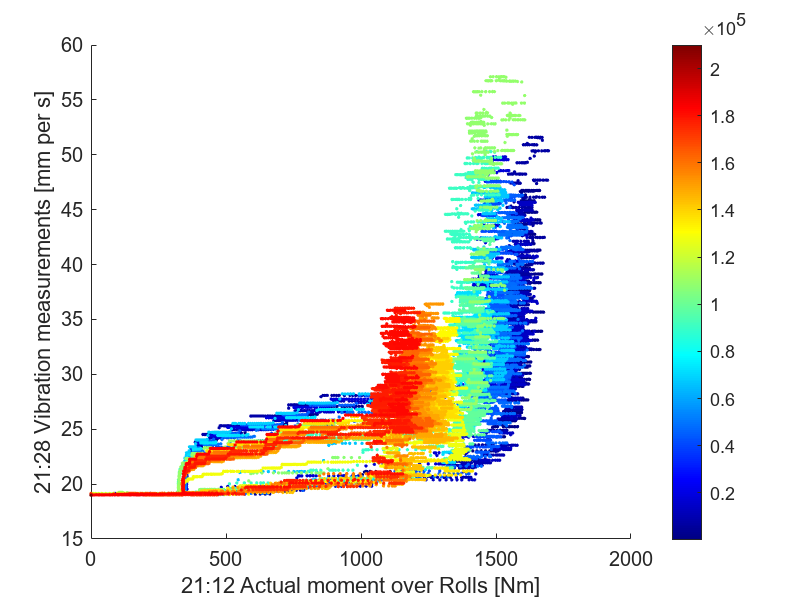

fileNum = 3;
fnPlotSignals(rawDataArray, fileNum, 3, 6, sensorNames);

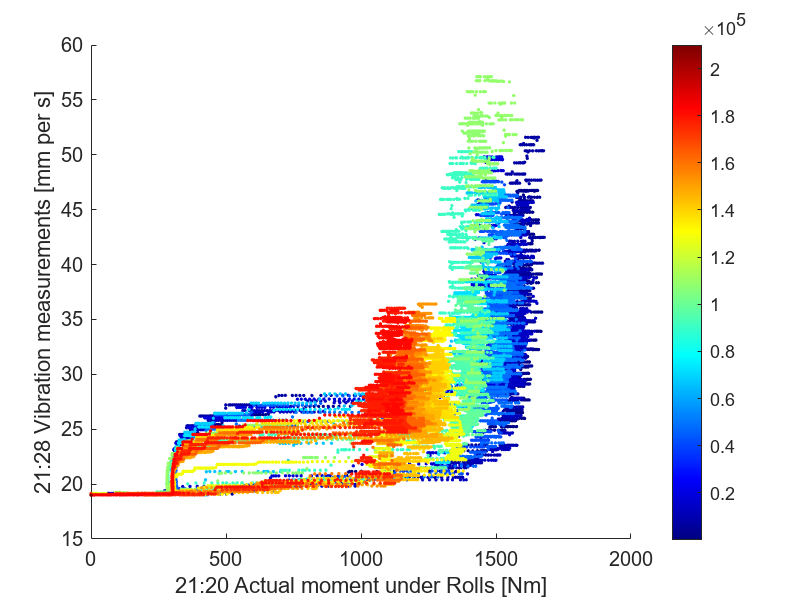

figure();
fileNum = 3;
signalIndex1 = 5;
signalIndex2 = 6;

numpoints = size(cell2mat(rawDataArray{fileNum}(1, 2)), 1);
pointidx = 1 : numpoints; 
sig1 = cell2mat(rawDataArray{fileNum}(signalIndex1, 2));
sig2 = cell2mat(rawDataArray{fileNum}(signalIndex2, 2));
scatter(sig1, sig2, 3, pointidx, 'filled');
colormap jet
colorbar
xlabel(char(sensorNames(signalIndex1)));
ylabel(char(sensorNames(signalIndex2)));
filename = "..\Latex Document\figures\File" + fileNum ...
    + "_Signal" + signalIndex1 ...
    + "vSignal" + signalIndex2;
print(filename,'-depsc','-tiff');
export_fig(filename, '-svg');

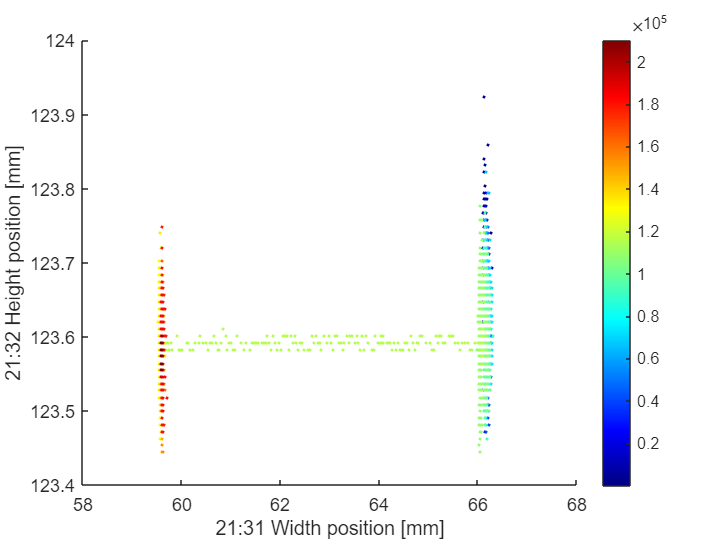

figure();
fileNum = 3;
signalIndex1 = 7;
signalIndex2 = 8;

numpoints = size(cell2mat(rawDataArray{fileNum}(1, 2)), 1);
pointidx = 1 : numpoints; 
sig1 = cell2mat(rawDataArray{fileNum}(signalIndex1, 2));
sig2 = cell2mat(rawDataArray{fileNum}(signalIndex2, 2));
scatter(sig1, sig2, 3, pointidx, 'filled');
colormap jet
colorbar
xlabel(char(sensorNames(signalIndex1)));
ylabel(char(sensorNames(signalIndex2)));

filename = "..\Latex Document\figures\File" + fileNum ...
    + "_Signal" + signalIndex1 ...
    + "vSignal" + signalIndex2;
%print(filename,'-depsc','-tiff');

## File 4

fileNum = 4;
arrTable = array2table(squeeze(r2Values(fileNum, :, :)), 'VariableNames', labels)

arrTable = 12×12 table
         1              2              3             4              5             6              7              8             9             10         11         12     
    ___________    ___________    ___________    __________    ___________    __________    ___________    ___________    __________    __________    ____    ___________
              1       0.066675     2.1472e-05      0.010025     0.00013623       0.01963       0.038803         0.4545       0.45591      0.026689    -Inf      0.0038445
       0.066675              1       0.022975    9.3809e-05

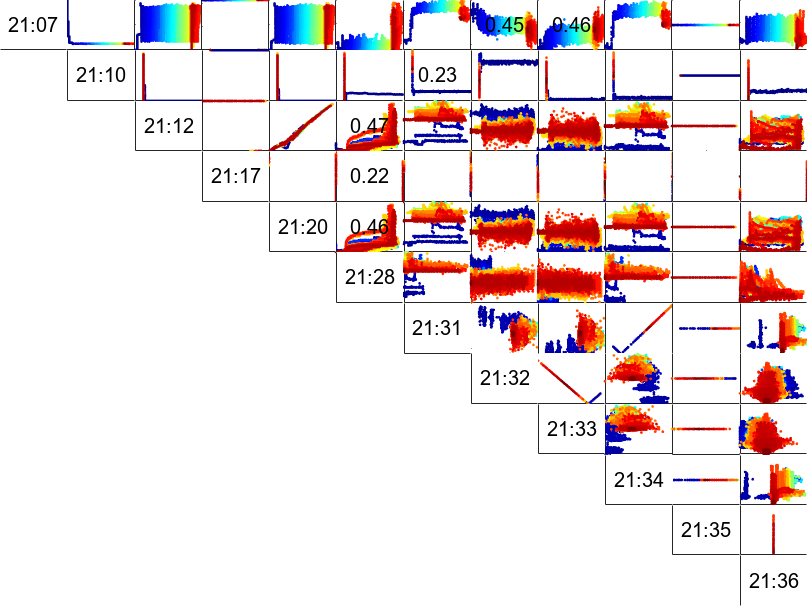

fnPlotCorrelations(rawDataArray, r2Values, fileNum, 0.2, 0.90, sensorNames, sensorNames);
filename = "..\Latex Document\figures\RawSignalCorrelationsFile" + fileNum;
%print(filename,'-depsc','-tiff');
filename = "..\Presentation\RawSignalCorrelationsFile" + fileNum;

print(filename, '-dsvg');

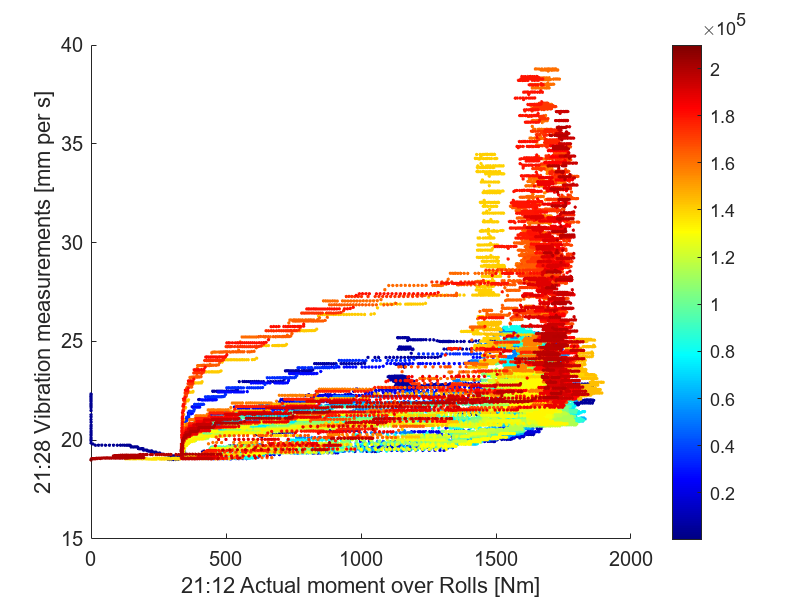

fnPlotSignals(rawDataArray, fileNum, 3, 6, sensorNames);

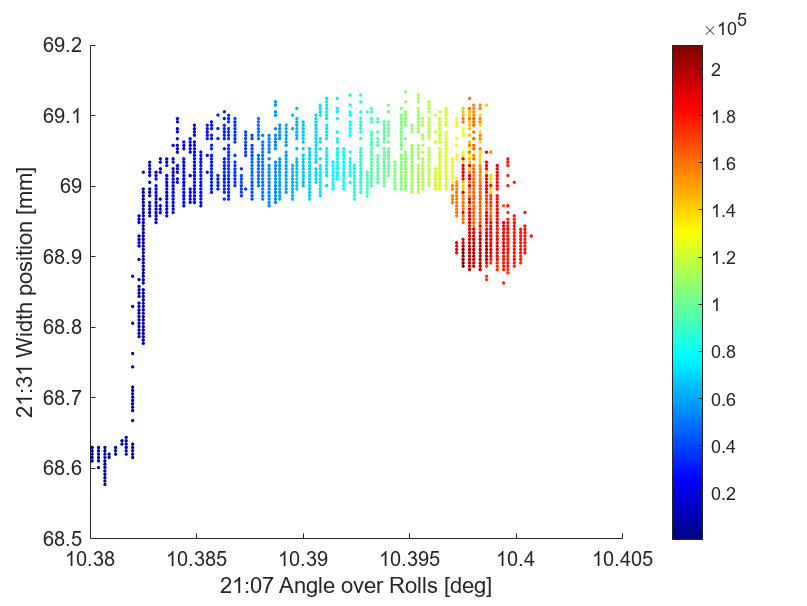

fnPlotSignals(rawDataArray, fileNum, 1, 7, sensorNames);

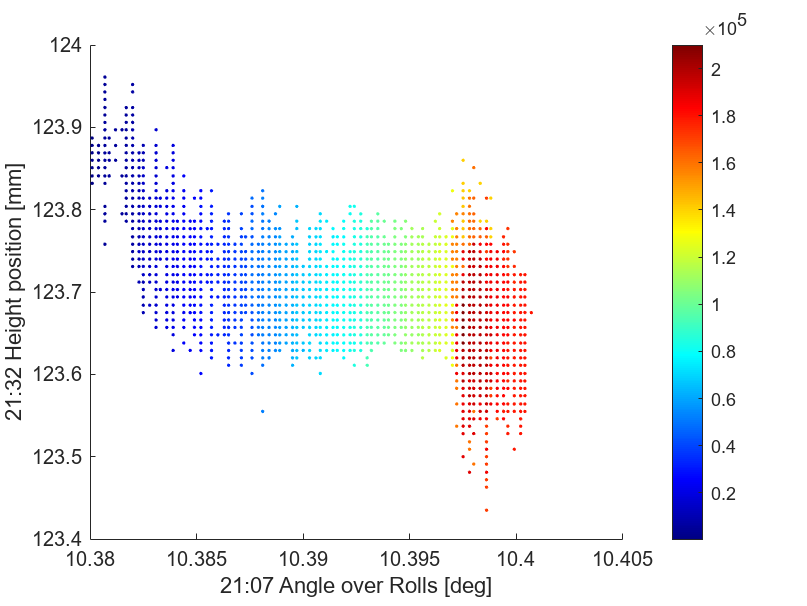

fnPlotSignals(rawDataArray, fileNum, 1, 8, sensorNames);

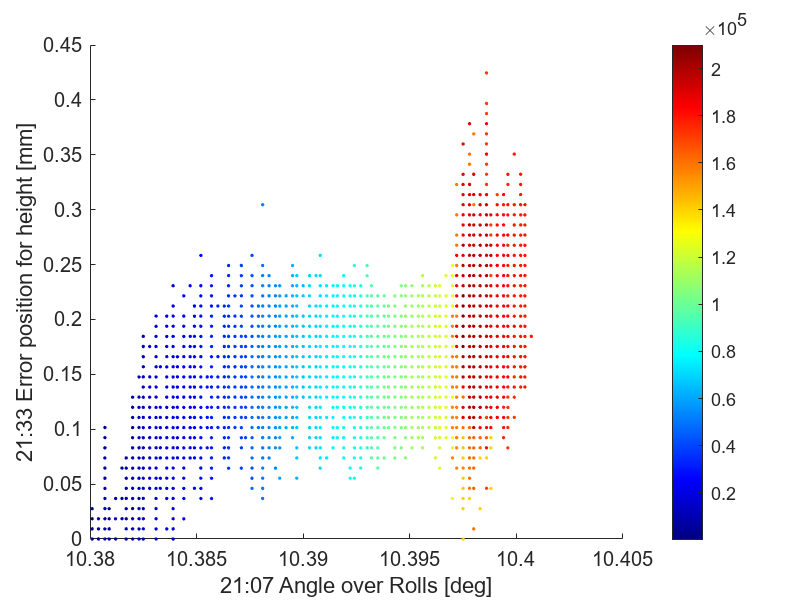

fnPlotSignals(rawDataArray, fileNum, 1, 9, sensorNames);

## File 5

fileNum = 5;
arrTable = array2table(squeeze(r2Values(fileNum, :, :)), 'VariableNames', labels)

arrTable = 12×12 table
        1              2             3             4              5             6              7              8             9             10         11         12     
    __________    ___________    __________    __________    ___________    __________    ___________    ___________    __________    __________    ____    ___________
             1        0.75956    0.00093403       0.27822      0.0020498     0.0017373         0.1786        0.26871     0.0003167       0.47184    -Inf       0.044473
       0.75956              1     0.0093203       0.25463      0.

%fnPlotCorrelations(rawDataArray, r2Values, fileNum, 0.2, 0.90, sensorNames, sensorNames);
filename = '..\Latex Document\figures\RawSignalCorrelationsFile' + fileNum;
%print(filename,'-depsc','-tiff');

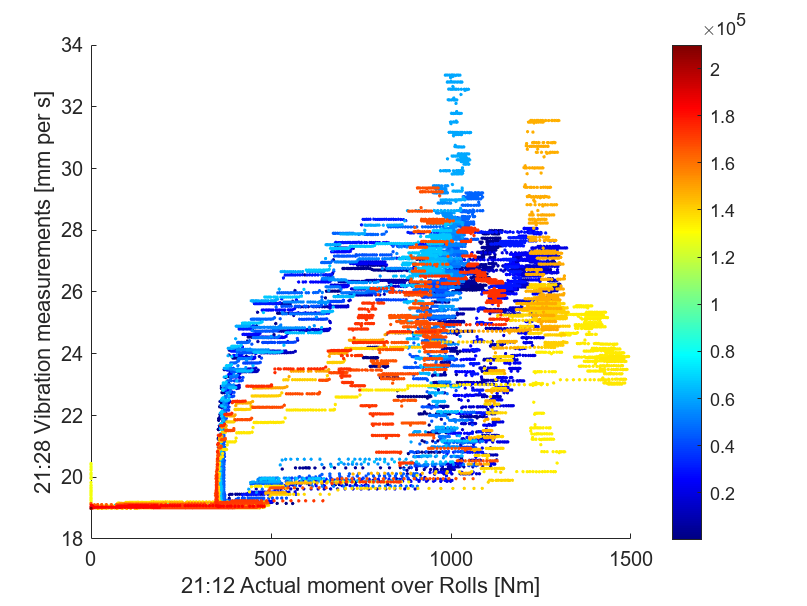

fnPlotSignals(rawDataArray, fileNum, 3, 6, sensorNames);

## File 8

fileNum = 8;
arrTable = array2table(squeeze(r2Values(fileNum, :, :)), 'VariableNames', labels)

arrTable = 12×12 table
        1              2             3             4             5             6              7             8              9             10          11         12     
    __________    ___________    __________    __________    __________    __________    ___________    __________    ___________    ___________    ____    ___________
             1        0.56081        0.2965       0.96089       0.26266       0.10073        0.86871        0.8844      2.712e-07       0.023539    -Inf        0.10469
       0.56081              1       0.35655       0.70595       0

%fnPlotCorrelations(rawDataArray, r2Values, fileNum, 0.2, 0.90, sensorNames, sensorNames);
filename = '..\Latex Document\figures\RawSignalCorrelationsFile' + fileNum;
%print(filename,'-depsc','-tiff');

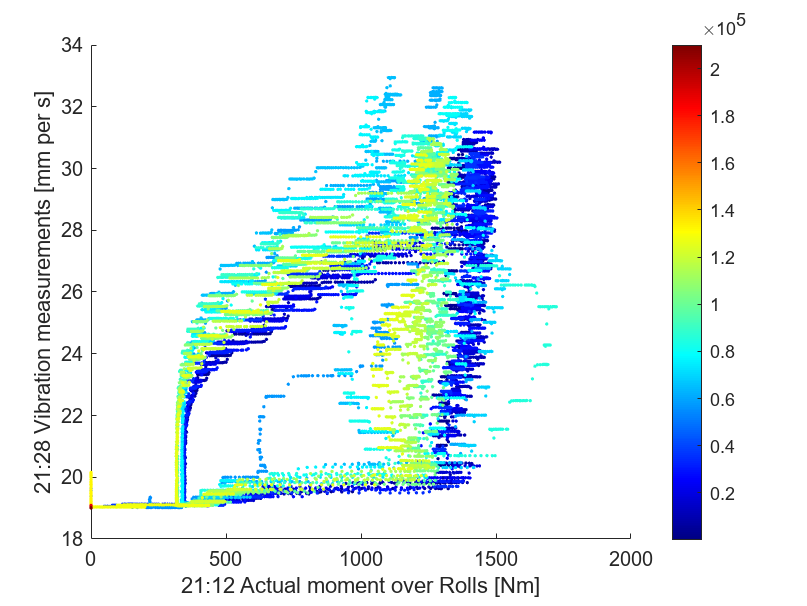

fnPlotSignals(rawDataArray, fileNum, 3, 6, sensorNames);

## File 13

fileNum = 13;
arrTable = array2table(squeeze(r2Values(fileNum, :, :)), 'VariableNames', labels)

arrTable = 12×12 table
        1             2            3             4            5           6            7             8             9            10        11         12    
    __________    __________    ________    ___________    ________    ________    __________    __________    __________    ________    ____    __________
             1      0.037184     0.54099       0.050071     0.49381     0.31584           0.9       0.89593      0.027724     0.48531    -Inf      0.065919
      0.037184             1    0.029656        0.84052    0.027188    0.010474      0.040667       0

%fnPlotCorrelations(rawDataArray, r2Values, fileNum, 0.2, 0.90, sensorNames, sensorNames);
filename = '..\Latex Document\figures\RawSignalCorrelationsFile' + fileNum;
%print(filename,'-depsc','-tiff');

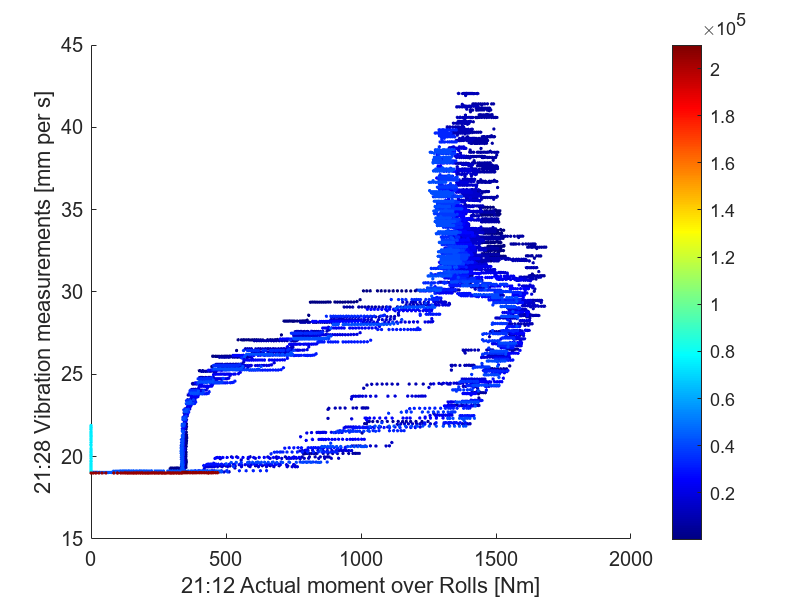

fnPlotSignals(rawDataArray, fileNum, 3, 6, sensorNames);

[FullPath,Filename,ext]=fileparts(matlab.desktop.editor.getActiveFilename);
currentFile = strcat(Filename, ext);
path = export(currentFile, Format="m", OpenExportedFile=false);